# Week 5 Exercise 2

clear
close all

Part (d)

help hamiltonian

  Generates hamiltonian matrix
    H = hamiltonian(Er,al,N)
    H, hamiltonian matrix
    Er, recoil energy
    al, normalized lattice depth
    N, number of momentum states



Part (e)

E_R = 1;
alpha = 10;
N = 5;

H = hamiltonian(E_R,alpha,N)

H =   100.0000   -2.5000         0         0         0         0         0         0         0         0         0
   -2.5000   64.0000   -2.5000         0         0         0         0         0         0         0         0
         0   -2.5000   36.0000   -2.5000         0         0         0         0         0         0         0
         0         0   -2.5000   16.0000   -2.5000         0         0         0         0         0         0
         0         0         0   -2.5000    4.0000   -2.5000         0         0         0         0         0
         0         0         0         0   -2.5000         0   -2.5000         0         0         0         0
         0         0         0         0         0   -2.5000    4.0000   -2.5000         0         0         0
         0         0         0         0         0         0   -2.5000   16.0000   -2.5000         0         0
         0         0         0         0         0         0         0   -2.5000   36.0000   -2.5000        

Part (f)

[V,D] = eig(H) % V:eigenvectors, D:eigenvalues

V =     0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0025   -0.0025    0.0489    0.0489   -0.7507    0.6570
    0.0001   -0.0004   -0.0005    0.0046   -0.0046    0.0628   -0.0628    0.7026    0.7026    0.0520   -0.0455
    0.0033   -0.0109   -0.0119    0.0873   -0.0872    0.6988   -0.6988   -0.0629   -0.0629   -0.0020    0.0018
    0.0510   -0.1407   -0.1438    0.6874   -0.6848   -0.0878    0.0878    0.0033    0.0033    0.0001   -0.0001
    0.3668   -0.6929   -0.5857   -0.1409    0.1494    0.0068   -0.0069   -0.0001   -0.0001   -0.0000    0.0000
    0.8519    0.0000    0.5217   -0.0000   -0.0460    0.0000    0.0010    0.0000    0.0000    0.0000   -0.0000
    0.3668    0.6929   -0.5857    0.1409    0.1494   -0.0068   -0.0069    0.0001   -0.0001    0.0000    0.0000
    0.0510    0.1407   -0.1438   -0.6874   -0.6848    0.0878    0.0878   -0.0033    0.0033   -0.0001   -0.0001
    0.0033    0.0109   -0.0119   -0.0873   -0.0872   -0.6988   -0.6988    0.0629   -0.0629    0.0018    0.00

D =    -2.1531         0         0         0         0         0         0         0         0         0         0
         0    3.4925         0         0         0         0         0         0         0         0         0
         0         0    5.6130         0         0         0         0         0         0         0         0
         0         0         0   16.1948         0         0         0         0         0         0         0
         0         0         0         0   16.2273         0         0         0         0         0         0
         0         0         0         0         0   36.0894         0         0         0         0         0
         0         0         0         0         0         0   36.0895         0         0         0         0
         0         0         0         0         0         0         0   64.0500         0         0         0
         0         0         0         0         0         0         0         0   64.0500         0        

Part (g)

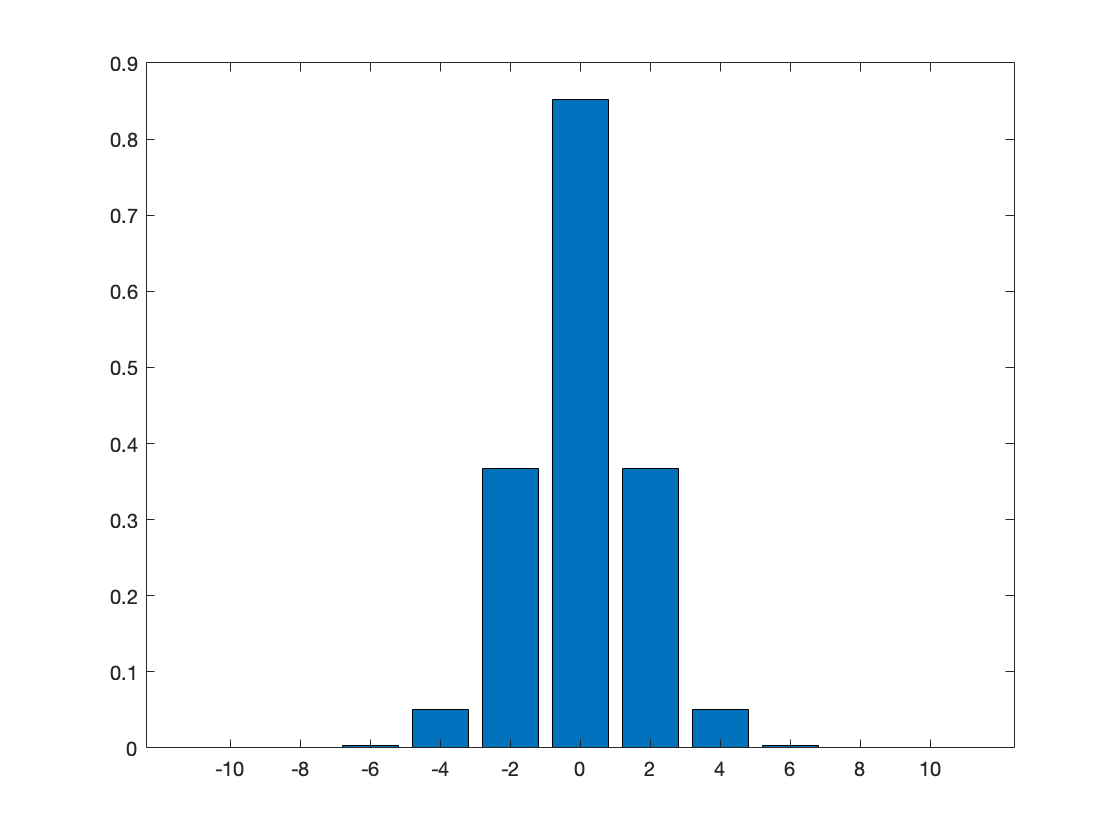

p = -2*N:2:2*N;

% First eigenvalue/vector
V1 = V(:,1);
D1 = D(1,1);

bar(p,V1)

Part (h)

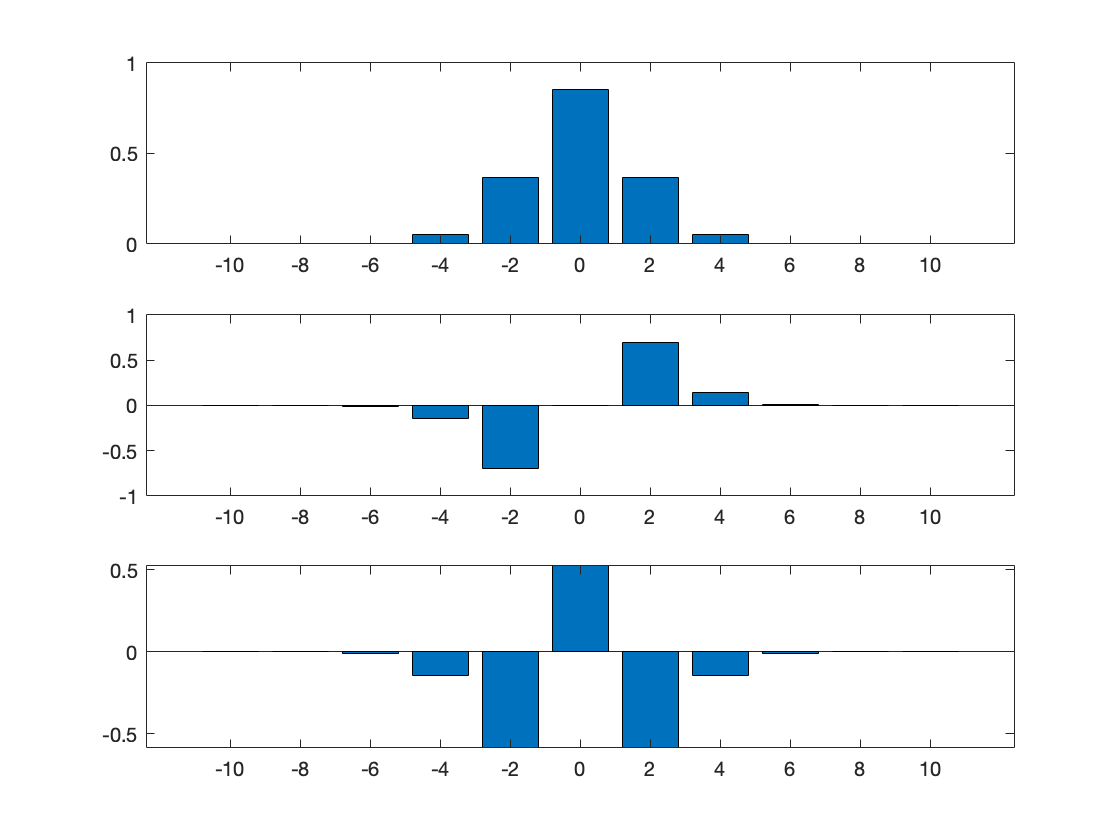

% Second Pair
V2 = V(:,2);
D2 = D(2,2);

% Third Pair
V3 = V(:,3);
D3 = D(3,3);

subplot(3,1,1)
bar(p,V1)
subplot(3,1,2)
bar(p,V2)
subplot(3,1,3)
bar(p,V3)